# Script to evaluate the "18 m/s Hurdles" for the LAC Summer Games 2025

**Task** 

Get the best possible wind preview (2s) by improving the baseline lidar data processing (LDP_v3)!

**Results 4BeamPulsed**

v3: Cost for Summer Games 2025 ("18 m/s hurdles"):  0.515998 m/s 

**Results CircularCW**

v3: Cost for Summer Games 2025 ("18 m/s hurdles"):  0.463842 m/s 

## 1. Setup

clearvars;close all;
clc;

% select LDP function
MyLDPfunction       = @LDP_vBolivia;

% select LidarType
LidarType           = '4BeamPulsed'; % [4BeamPulsed/CircularCW]

% Seeds (can be adjusted, but will provide different results)
nSeed               = 6;                        % [-]	    number of stochastic turbulence field samples
Seed_vec            = (1:nSeed)+18*100         % [-]  	    vector of seeds

Seed_vec =         1801        1802        1803        1804        1805        1806


% Parameters postprocessing (can be adjusted, but will provide different results)
t_start             = 60;                       % [s] 	    ignore data before for STD and spectra
TMax                = 660;                      % [s]       total run time
DT                  = 0.01;                     % [s]       time step
time                = (0:DT:TMax)';             % [s]       time vector

% Parameter for Cost (Summer Games 2025)
tau                 = 2;                        % [s]       time to overcome pitch actuator, from Example 1: tau = T_Taylor - T_buffer, since there T_filter = T_scan = 0

switch LidarType
    case '4BeamPulsed'
        % configuration from LDP_v1_4BeamPulsed.IN and FFP_v1_4BeamPulsed.IN
        LDP.NumberOfBeams       = 4;            % [-]       Number of beams measuring at different directions               
        LDP.AngleToCenterline   = 19.176;       % [deg]     Angle around centerline
        LDP.IndexGate           = 6;            % [-]       IndexGate
        LDP.FlagLPF             = 1;            % [0/1]     Enable low-pass filter (flag)
        LDP.omega_cutoff        = 0.13;         % [rad/s]   Corner frequency (-3dB) of the low-pass filter
        LDP.T_buffer            = 0.2;          % [s]       Buffer time for filtered REWS signal
    case 'CircularCW'
        % configuration from LDP_v1_CircularCW.IN and FFP_v1_CircularCW.IN
        LDP.NumberOfBeams       = 50;           % [-]       Number of beams measuring at different directions               
        LDP.AngleToCenterline   = 15;           % [deg]     Angle around centerline
        LDP.IndexGate           = 1;            % [-]       IndexGate
        LDP.FlagLPF             = 1;            % [0/1]     Enable low-pass filter (flag)
        LDP.omega_cutoff        = 0.20;         % [rad/s]   Corner frequency (-3dB) of the low-pass filter
        LDP.T_buffer            = 4.2;          % [s]       Buffer time for filtered REWS signal        
end

## 2. Postprocessing: evaluate data

% Files (should not be be changed)
SimulationFolderLAC     = 'solis_lidar_data';

% Allocation
MAE     = NaN(1,nSeed); % mean absolute error [m/s]

% Loop over all seeds
iSeed = 1;       
% for iSeed = 1:nSeed       

    % Load, interpolate and extrapolate data
    Seed                                = Seed_vec(iSeed);
	WindFileName                        = ['URef_18_Seed_',num2str(Seed,'%02d')];
    SolisResultFile                     = fullfile(SimulationFolderLAC,[WindFileName,'_lidar_data_',LidarType,'.csv']);
    SolisData                           = readtable(SolisResultFile)    

SolisData = 2640×22 table
    time    beamID    lineOfSightWindSpeed1    lineOfSightWindSpeed2    lineOfSightWindSpeed3    lineOfSightWindSpeed4    lineOfSightWindSpeed5    lineOfSightWindSpeed6    lineOfSightWindSpeed7    lineOfSightWindSpeed8    lineOfSightWindSpeed9    lineOfSightWindSpeed10    isValid1    isValid2    isValid3    isValid4    isValid5    isValid6    isValid7    isValid8    isValid9    isValid10
    ____    ______    _____________________    _____________________    _____________________    ___________________

    beamID                              = interp1(SolisData.time,SolisData.beamID,time,'previous','extrap');
    isValid                             = interp1(SolisData.time,SolisData.("isValid"+LDP.IndexGate),time,'previous','extrap');
    lineOfSightWindSpeed                = interp1(SolisData.time,SolisData.("lineOfSightWindSpeed"+LDP.IndexGate),time,'previous','extrap');    

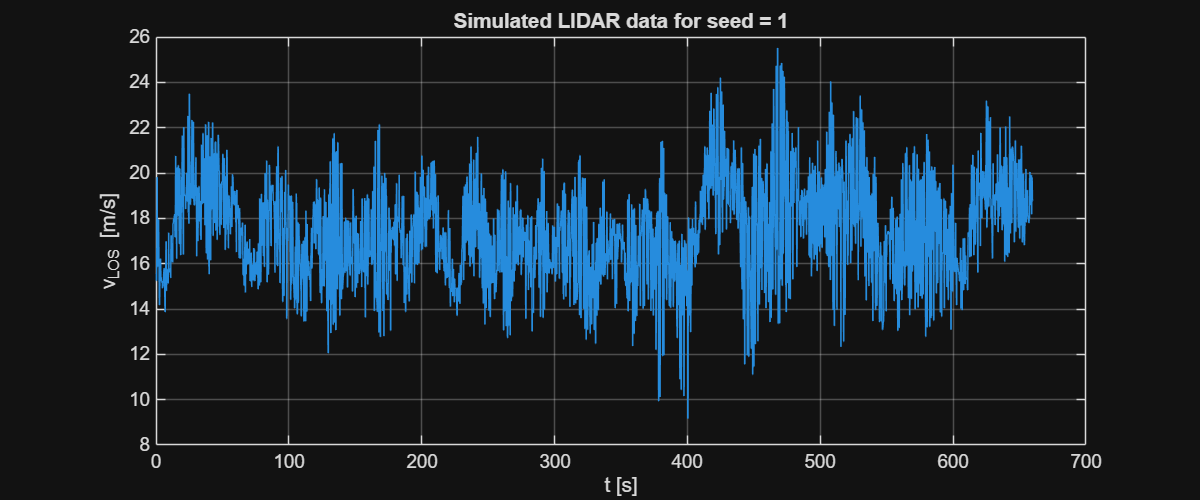

    idx = logical(isValid);
    f_width = 1200;f_height = 500;
    fontsize = 14;

    f = figure;
    f.Position([3 4]) = [f_width f_height];

    plot(time(idx),lineOfSightWindSpeed(idx))
    xlabel('t [s]'); ylabel("v_{LOS} [m/s]")
    title(['Simulated LIDAR data for seed = ',num2str(iSeed)])

    ax = gca;
    ax.FontSize = fontsize;
    grid on

    % Get REWS from the wind field 
    RewsFile                 	        = ['TurbulentWind\URef_18_Seed_',num2str(Seed,'%02d'),'.csv'];  
    RewsData                            = readtable(RewsFile)

RewsData = 2400×2 table
    time     REWS 
    ____    ______
       0    17.844
    0.25    17.824
     0.5    17.815
    0.75     17.79
       1    17.723
    1.25    17.721
     1.5    17.657
    1.75    17.629
       2    17.552
    2.25     17.46
     2.5    17.471
    2.75    17.557
       3     17.55
    3.25    17.526
     3.5    17.508
    3.75    17.505

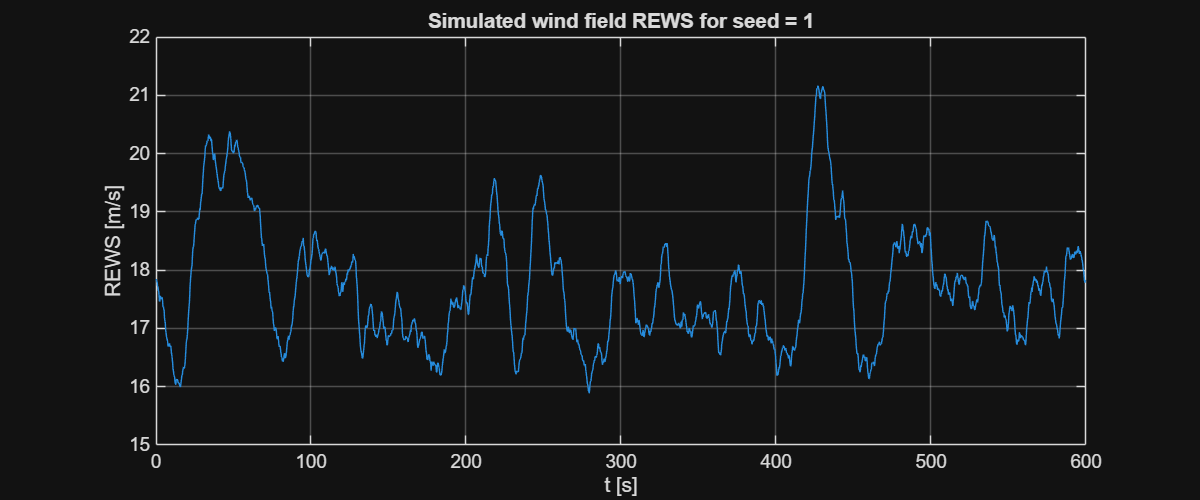

    f = figure;
    f.Position([3 4]) = [f_width f_height];

    plot(RewsData.time,RewsData.REWS)
    xlabel('t [s]'); ylabel("REWS [m/s]")
    title(['Simulated wind field REWS for seed = ',num2str(iSeed)])

    ax = gca;
    ax.FontSize = fontsize;
    grid on

    REWS_WindField                      = interp1([RewsData.time;RewsData.time+600],[RewsData.REWS;RewsData.REWS],time); % REWS is circular 
    REWS_WindField_shifted              = interp1([RewsData.time;RewsData.time+600],[RewsData.REWS;RewsData.REWS],time+tau);

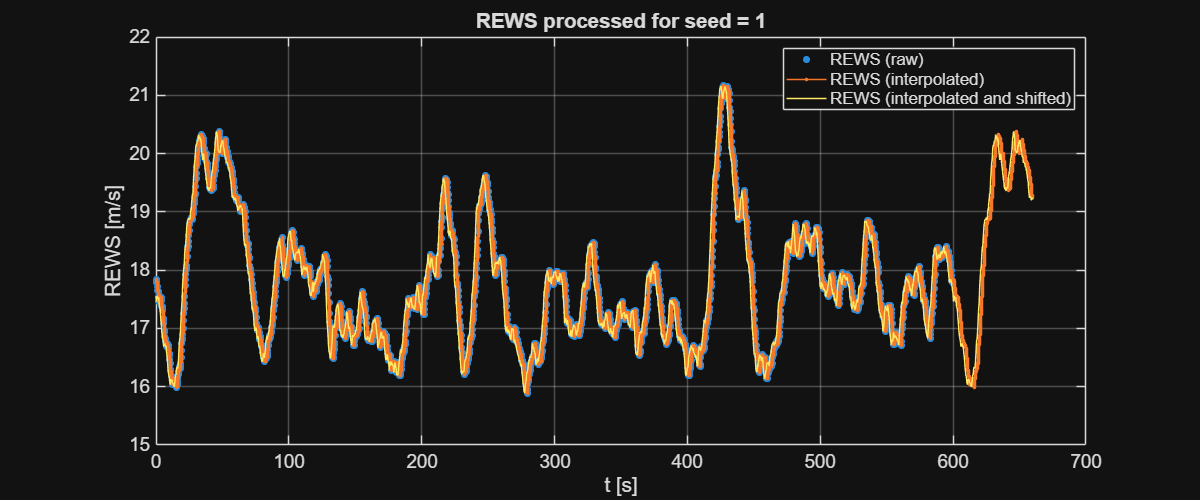

    f = figure;
    f.Position([3 4]) = [f_width f_height];

    plot(RewsData.time,RewsData.REWS,".",MarkerSize=16)
    hold on
    plot(time,REWS_WindField,".-",MarkerSize=8)
    plot(time,REWS_WindField_shifted)
    hold off
    xlabel('t [s]'); ylabel("REWS [m/s]")
    legend('REWS (raw)','REWS (interpolated)','REWS (interpolated and shifted)',Interpreter='none')
    title(['REWS processed for seed = ',num2str(iSeed)])

    ax = gca;
    ax.FontSize = fontsize;
    grid on

    % Calculate REWS from the lidar data
    clear(func2str(MyLDPfunction)) % clearing all persistent variables from previous call 
    [REWS,REWS_f,REWS_b]                = MyLDPfunction(time,isValid,beamID,lineOfSightWindSpeed,DT,LDP);

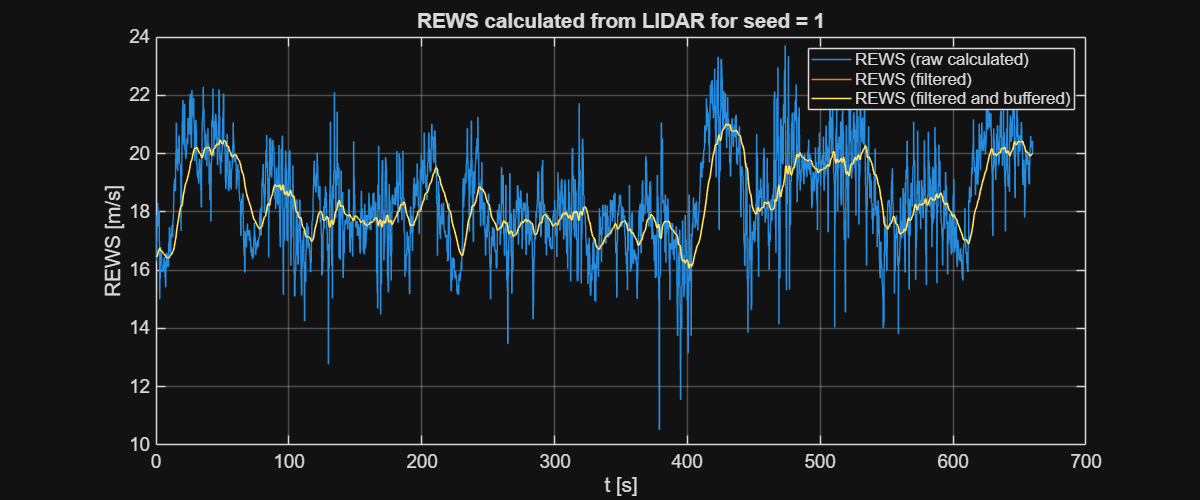

    f = figure;
    f.Position([3 4]) = [f_width f_height];

    plot(time,REWS)
    hold on
    % plot(time,REWS_f,".",MarkerSize=8)
    plot(time,REWS_f)
    % plot(time,REWS_b,".",MarkerSize=8)
    plot(time,REWS_b)
    hold off
    xlabel('t [s]'); ylabel("REWS [m/s]")
    legend('REWS (raw calculated)','REWS (filtered)','REWS (filtered and buffered)',Interpreter='none')
    title(['REWS calculated from LIDAR for seed = ',num2str(iSeed)])

    ax = gca;
    ax.FontSize = fontsize;
    grid on

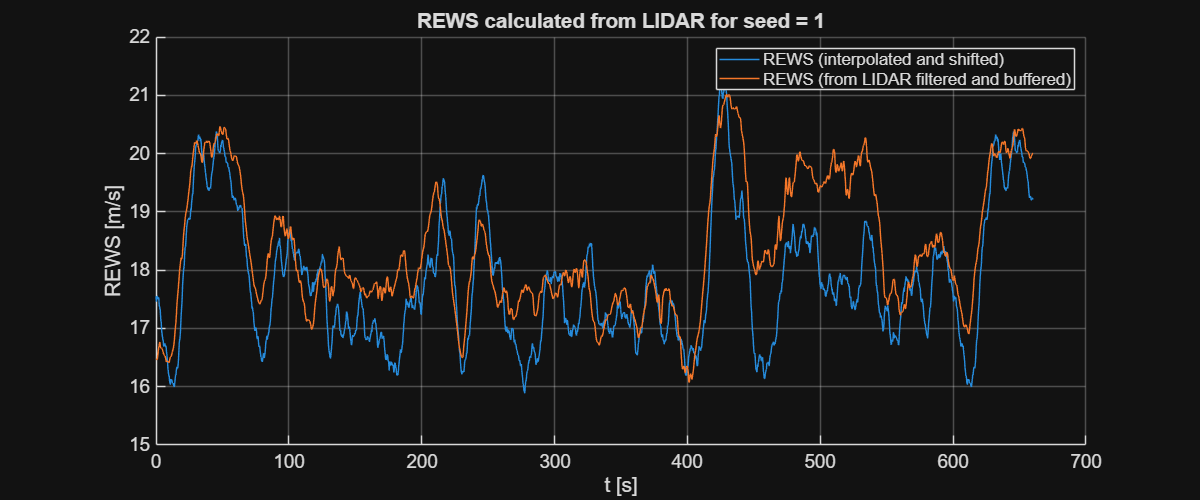

    f = figure;
    f.Position([3 4]) = [f_width f_height];

    hold on
    plot(time,REWS_WindField_shifted)
    plot(time,REWS_b)
    hold off
    xlabel('t [s]'); ylabel("REWS [m/s]")
    legend('REWS (interpolated and shifted)','REWS (from LIDAR filtered and buffered)',Interpreter='none')
    title(['REWS calculated from LIDAR for seed = ',num2str(iSeed)])

    ax = gca;
    ax.FontSize = fontsize;
    grid on

    % Calculate mean absolute error
    Error                               = REWS_WindField_shifted-REWS_b;                    % error is  REWS from wind field shifted minus REWS from lidar filtered and buffered.
    MAE(iSeed)                          = mean(abs(detrend(Error(time>=t_start),'constant'))); % only consider error after t_start 
             
    % Plot REWS for absolute error             
    figure('Name',['REWS seed ',num2str(Seed)])
    subplot(311)
    hold on; grid on; box on
    plot(time,  REWS_WindField);
    plot(time,  REWS);
    ylabel('REWS [m/s]');
    legend('wind field','lidar estimate')
    subplot(312)
    hold on; grid on; box on
    plot(time,  REWS_WindField_shifted);
    plot(time,  REWS_b);
    ylabel('REWS [m/s]');
    legend('wind field shifted','lidar estimate filtered and buffered')
    subplot(313)
    hold on; grid on; box on
    plot(time,  Error);
    ylabel('error [m/s]');
    xlabel('time [s]')

end

## Calculation of Cost for Summer Games 2025

Cost                        = mean(MAE);
fprintf('Cost for Summer Games 2025 ("18 m/s hurdles"):  %f \n',Cost);